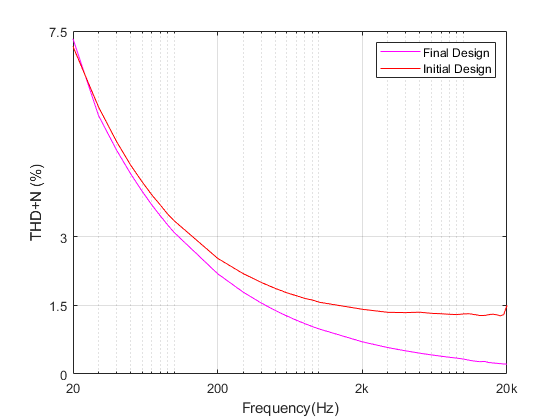

close all

files2 = dir(fullfile('C:\Users\jhend_000\Documents\MATLAB\Final_Design', '*.WAV'));
files3 = dir(fullfile('C:\Users\jhend_000\Documents\MATLAB\ADCDISABLE_PC', '*.WAV'));

my_Files2 = natsortfiles({files2.name});
my_Files3 = natsortfiles({files3.name});
y = [20 30 40 50 60 70 80 90 100 200 300 400 500 600 700 800 900 1000 2000 3000 4000 5000 6000 7000 8000 9000 10000 11000 12000 13000 14000 15000 16000 17000 18000 19000 20000];

thdPlusN2 = zeros(1,37);
thdPlusN3 = zeros(1,37);
thdPlusNDiff = zeros(1,37);

rmsAns2 = zeros(1,37);
rmsAns3 = zeros(1,37);

rms2 = zeros(1,37);
rms3 = zeros(1,37);

for i = 1:37    
    
    w0 = y(i)/(44100/2);
    bw = w0/3;
    
    [d, c] = iirnotch(w0,bw);
    [f, e] = iirnotch(w0,bw);
   
    [myRead2, F2] = audioread(my_Files2{i});
    [myRead3, F3] = audioread(my_Files3{i});
  
    rms2(i) = rms(myRead2);
    rms3(i) = rms(myRead3);
  
    rmsAns2(i) = rms(filter(d,c,myRead2));
    rmsAns3(i) = rms(filter(f,e,myRead3));
  
    thdPlusN2(i) = sqrt((power(rmsAns2(i),2))/(power(rms2(i),2)))*100;
    thdPlusN3(i) = sqrt((power(rmsAns3(i),2))/(power(rms3(i),2)))*100;
    thdPlusNDiff(i) = thdPlusN3(i) - thdPlusN2(i);
    
end
 
    semilogx(y,thdPlusN2, 'm');
    xlabel('Frequency(Hz)')
    ylabel('THD+N (%)')
    xticks([20 200 2000 20000])
    yticks([0 1.5 3 7.5])
    xticklabels({'20','200','2k','20k'})
    yticklabels({'0','1.5','3','7.5'})
    xlim([0 20000])
    ylim([0 7.5])
    grid on
    hold on
  
    semilogx(y,thdPlusN3, 'r');
    xlabel('Frequency(Hz)')
    ylabel('THD+N (%)')
    xticks([20 200 2000 20000])
    yticks([0 1.5 3 7.5])
    xticklabels({'20','200','2k','20k'})
    yticklabels({'0','1.5','3','7.5'})
    xlim([0 20000])
    ylim([0 7.5])
   % title('THD+N versus Frequency Comparisson Between Initial and Final Designs')
    grid on
    legend('Final Design','Initial Design')